**Step 1 – Raw Signals**

We have two sets of measurements, taken at the same time points. Let’s plot them and ask: Do we see a rhythm by eye?

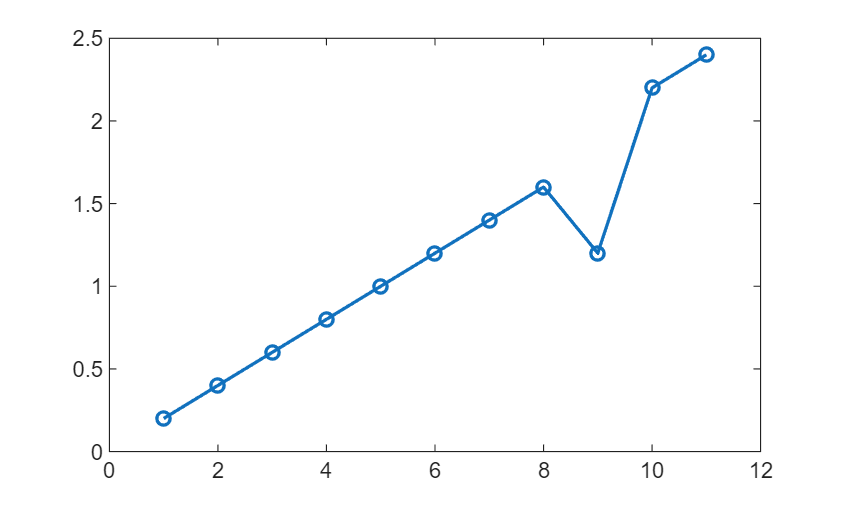

time = 1:11; % minutes

signal1 = [0.2 0.4 0.6 0.8 1 1.2 1.4 1.6 1.2 2.2 2.4];
signal2 = [3 6 3 0 3 6 3 0 3 6 3 0];

figure;
plot(time, signal1, 'o-', 'LineWidth', 1.5); hold on;

plot(time, signal2, 's-', 'LineWidth', 1.5);

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

xlabel('Time (minutes)');
ylabel('Signal');
title('Step 1: Raw measured signals');
legend('Signal 1','Signal 2');
grid on;

**Step 2 – Fourier Decomposition**

We use the Fast Fourier Transform (FFT) to break down each signal into its frequency components.

The Discrete Fourier Transform (DFT) of a signal 

x[n] with N points is:


$$X\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-\textrm{i2}\pi \textrm{kn}//N} ,k=0,1,\ldotp \ldotp \ldotp ,N-1$$


This produces complex coefficients X[k] representing oscillations at different frequencies.

The Fast Fourier Transform (FFT) is a computationally efficient way to calculate this.

function [t_fine, recon, f_pos, mag_pos, dom_freq, dom_period] = analyze_fft(time, signal)
    N = length(signal);
    dt = 1; % 1 minute between samples
    signal_detrended = signal - mean(signal);

    % FFT
    fft_vals = fft(signal_detrended);
    fft_freqs = (0:N-1)/(N*dt);

    % Keep only positive frequencies
    half = floor(N/2);
    f_pos = fft_freqs(1:half);
    mag_pos = abs(fft_vals(1:half));

    % Find dominant frequency (ignore DC)
    [~, idx] = max(mag_pos(2:end));
    idx = idx + 1;
    dom_freq = f_pos(idx);
    dom_period = 1/dom_freq;

    % Reconstruct rhythm
    t_fine = linspace(time(1), time(end), 500);
    amp = mag_pos(idx)/N;
    phase = angle(fft_vals(idx));
    recon = amp * cos(2*pi*dom_freq*t_fine + phase) + mean(signal);
end

**Step 3 – FFT Spectra**

Now we compute the FFT for both signals and plot their spectra.

The corresponding frequency values are given by:


$$fk = \frac{k}{N \cdot \Delta t} , where \Delta t = sampling \spaceinterval \space(min)$$


[t1, recon1, f1, mag1, fdom1, pdom1] = analyze_fft(time, signal1);
[t2, recon2, f2, mag2, fdom2, pdom2] = analyze_fft(time, signal2);

figure;
stem(f1, mag1, 'r','LineWidth',1.5); hold on;
stem(f2, mag2, 'g','LineWidth',1.5);
xlabel('Frequency (cycles/min)');
ylabel('Magnitude');
title('Step 3: FFT spectra of both signals');
legend('Signal 1','Signal 2');
grid on;

**Step 4 – Identify the Dominant Rhythm**

The dominant frequency corresponds to the largest nonzero peak in the spectrum.

The period of this rhythm is simply the reciprocal:


$$T = \frac{1}{f_{dominant}}$$


fprintf('Step 4 results:\n');
fprintf(' Signal 1: dominant frequency = %.3f cycles/min, period = %.2f min\n', fdom1, pdom1);
fprintf(' Signal 2: dominant frequency = %.3f cycles/min, period = %.2f min\n', fdom2, pdom2);

**Step 5 – Reconstruct the Dominant Rhythm**

We can reconstruct a cosine wave with the dominant frequency, amplitude, and phase: 


$$x_{recon} (t) = Acos(2\pi f_{dom} t + \phi) + \mu
\\
where \spaceA \space is \space the\spaceamplitude,\space \phi\space is \space the \space phase \space and \space \mu \space is \space the \space mean \space of \space the \space signal.$$


Then overlay the reconstructed cosine wave (dominant frequency) on top of the raw data.

figure;
plot(time, signal1, 'o-', 'LineWidth', 1.5); hold on;
plot(t1, recon1, 'r--', 'LineWidth', 1.5);
plot(time, signal2, 's-', 'LineWidth', 1.5);
plot(t2, recon2, 'g--', 'LineWidth', 1.5);
xlabel('Time (minutes)');
ylabel('Signal');
title('Step 5: Raw signals with reconstructed rhythms');
legend('Signal 1 raw','Signal 1 rhythm','Signal 2 raw','Signal 2 rhythm');
grid on;

**Step 6 – Compare and Average**

Finally, we compare both signals and compute the average signal to reveal the shared ultradian rhythm. To emphasize shared rhythms, we can average the two signals first, then apply FFT.

avg_signal = (signal1 + signal2)/2;
[t_avg, recon_avg, f_avg, mag_avg, fdom_avg, pdom_avg] = analyze_fft(time, avg_signal);

figure;
subplot(1,2,1);
plot(time, avg_signal, 'k*-','LineWidth',1.5); hold on;
plot(t_avg, recon_avg, 'b--','LineWidth',1.5);
xlabel('Time (minutes)');
ylabel('Signal');
title('Step 6a: Average signal with rhythm');
legend('Average raw','Average rhythm');
grid on;

subplot(1,2,2);
stem(f_avg, mag_avg, 'b','LineWidth',1.5);
xlabel('Frequency (cycles/min)');
ylabel('Magnitude');
title('Step 6b: FFT of averaged signal');
grid on;

fprintf('Step 6 (average): dominant frequency = %.3f cycles/min, period = %.2f min\n', fdom_avg, pdom_avg);
